load('R300KWorkspace.mat')
RW=(Resistance300K)./(ResErr).^2;
W=1./(ResErr).^2;
RWsum = sum(RW,'all');
Wsum=sum(W,'all');
Rweighted=(RWsum/Wsum)

Rweighted = 0.2938

RoverR300=[1 1.43 1.87 2.34 2.85 3.36 3.88 4.41 4.95 5.48 6.03 6.58 7.14 7.71 8.28 8.86 9.44 10.03 10.63 11.24 11.84 12.46 13.08 13.72 14.34 14.99 15.63 16.29 16.95 17.62 18.28 18.97 19.66 26.35];
T=100.*[3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36];

Rweighted =

    0.2938

# T vs R

Linear model Poly1:

     f(x) = p1*x + p2

Coefficients (with 95% confidence bounds):

       p1 =       156.2  (145.9, 166.4)

       p2 =       352.8  (230.5, 475.2)

Goodness of fit:

  SSE: 1.05e+06

  R-square: 0.9679

  Adjusted R-square: 0.9669

  RMSE: 181.1

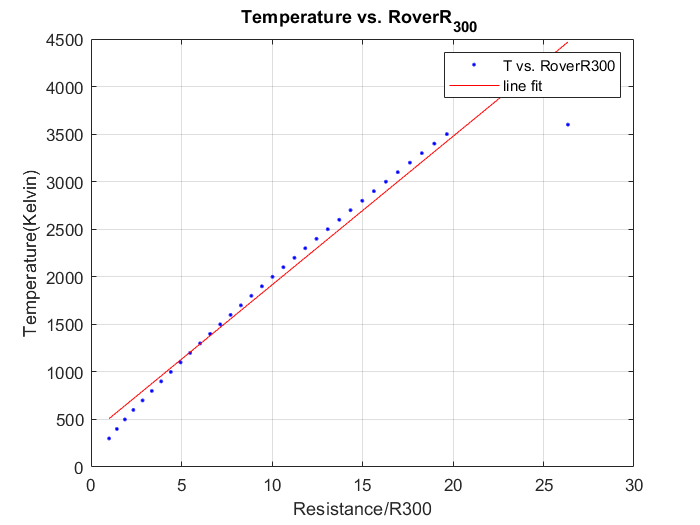

[xData, yData] = prepareCurveData( RoverR300, T);

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'T vs. RoverR300', 'line fit', 'Location', 'NorthEast' );
% Label axes
xlabel Resistance/R300
ylabel Temperature(Kelvin)
title('Temperature vs. RoverR_{300} ')
grid on